### Load neural data

m = F;
MName = F.AnimalID;
m_neural = m.MS{1}.FiltTraces(901:end,m.MS{1}.goodCellVec); % remove first 2 min
m_tstamp = m.TimeStamp.Ts{1}.Ms(901:end);
m_neural_bined = BinData(m_neural, 5, 'mean'); % bin to 1/3 s
m_tstamp_bined = BinData(m_tstamp, 5, 'mean');

### Load tracking data

tracks_matrix_raw = h5read('PairQD1_XZ98.h5','/tracks');

Error using h5readc
Unable to open 'PairQD1_XZ98.h5'. File or folder not found.

Error in h5read (line 93)
[data,var_class] = h5readc(Filename,Dataset,start,count,stride);

disp(size(tracks_matrix_raw))
% frames x nodes x 2 (x,y) x tracks
% nose earR earL tailbase body
% fill NAs
tracks_matrix_raw = fillmissing(tracks_matrix_raw, 'movmean', 7);

### Read timestamp and bin data, trucate tracking to match length, align timestamp

% match bv timestamp and bv video (tracking)
tstamp_raw = csvread('PairQD1_XZ98.csv', 1);
tstamp_raw = tstamp_raw(size(tstamp_raw,1)-size(tracks_matrix_raw,1)+1:end,2); % match video
% match neural data timestamp 
% neural is almost always shorter (remove first 1-2 minutes) whereas bv
% only ~200-600 frames
neural_starts_here = find(tstamp_raw>=m_tstamp(1),1)
tracks_matrix = tracks_matrix_raw(neural_starts_here:end,:,:,:);
tstamp = tstamp_raw(neural_starts_here:end);


% bin Data
tracks_bined = BinData(tracks_matrix, 10, 'mean');
time_bined = BinData(tstamp, 10, 'mean');
% find approximate head position by finding mid point between nose and body
head_coord = 1/2*(tracks_bined(:,1,:,:) + tracks_bined(:,5,:,:));
% timestamp map
[idx1,idx2,tdifference] = TStampAlign(time_bined,m_tstamp_bined);
figure, plot(tdifference);
m_tstamp_bined = m_tstamp_bined(idx2,:);
m_neural_bined = m_neural_bined(idx2,:);

### Quadrant position states

qcenter = [236,294]; %[ycenter, xcenter]
qcode = [head_coord(:,:,1)<=qcenter(1), head_coord(:,:,2) > qcenter(2)];
qseries = [qcode(:,1)+qcode(:,2)*2];
qseries(qseries==1) = 4; qseries(qseries == 0) = 1;
[b,bg,bp] = groupcounts(qseries);
% time spent in each quadrant
colors = maxdistcolor(length(bp), @sRGB_to_CIELab,'Lmin',0.6,'Lmax',0.8,'Cmin',0.5,'Cmax',0.7);
figure, pie(bp/100);legend(num2str(bg)); colormap(colors);

### Get PCs and overlay plot with quadrant state

coef = pca(zscore(m_neural));
PCs = m_neural * coef;
[onset, offset] = FindConsecutiveOnsetOffset(qseries);
figure, ax = subplot(2,1,1,'NextPlot','add'); plot(ax,m_tstamp/1000,PCs(:,2),'r');

% patch each quadrant
for qn = 1:length(onset)
    onset_t = onset{qn}; offset_t = offset{qn};ccolor = colors(qn,:);
    for i = 1:length(onset_t)
        patch(ax,1/1000*time_bined([onset_t(i),offset_t(i),offset_t(i),onset_t(i)]),[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],ccolor,'FaceAlpha',0.15, 'EdgeAlpha',0.14);
    end
end
title('PC');
% plot average plot
subplot(2,1,2);plot(m_tstamp_bined/1000, mean(m_neural_bined,2),'b-');
title('Average trace');

### Prepare training/test set

o_idx = find(qseries==1); % quadrant 1
t_idx = find(qseries==2); % 2
th_idx = find(qseries==3); % 3
f_idx = find(qseries==4); % 4
idxs = {o_idx, t_idx, th_idx, f_idx};
Y = qseries;
% prepare training/test set
m_neural_bined = zscore(m_neural_bined);

### One vs all

f = figure;
for kd = 1:4    
    fold = 10;
    Y_temp = Y; 
    Y_temp(idxs{kd}) = 1;Y_temp(setdiff(1:length(Y_temp), idxs{kd})) = 0;
    part_temp = cvpartition(Y_temp, 'KFold', fold);
    perform = [];
    perform_shifted = [];
    for k = 1:fold*10
        foldN = mod(k, fold); if foldN == 0 foldN = fold; end
        training_idx = training(part_temp, foldN);
        Y_temp_training = Y_temp(training_idx);
        X_train = m_neural_bined(training_idx,:);
        Mdl = fitcdiscr(X_train,Y_temp_training);
        % test
        val_idx = test(part_temp, foldN);
        Y_temp_val = Y_temp(val_idx);
        X_val = m_neural_bined(val_idx,:);
        Y_pred = predict(Mdl, X_val);
        perform = [perform; sum((Y_temp_val == Y_pred))/length(Y_temp_val)];
        if mod(k,fold) == 0
            part_temp = repartition(part_temp);
        end
        for cs = 1:10
%             X_train_shifted = circshift(X_train, randi(size(X_train,1)),1);
            X_train_shifted = X_train(randperm(size(X_train,1)),:);
            Mdl_shifted = fitcdiscr(X_train_shifted,Y_temp_training);
            % evaluate performance
            Y_pred_s = predict(Mdl_shifted, X_val);
            perform_shifted = [perform_shifted; sum((Y_temp_val == Y_pred_s))/length(Y_temp_val)];
        end
    end
    a = subplot(2,2,kd,'Parent',f);
    XZBoxPlot({perform,perform_shifted},[],[],{MName,'shuffled'},[],a);
    random_guess_ = max(length(idxs{kd})/length(Y_temp), 1-length(idxs{kd})/length(Y_temp));
    line(a, a.XLim, [random_guess_, random_guess_],'LineStyle','--');
    title([num2str(kd),'-vs-all']); ylabel('Accuracy'); ylim('padded');
end

### One vs one

f = figure;
% 6 comparisons 1v2 2v3 3v4 1v4 2v4 1v3
combines = nchoosek(1:4,2);
for kd = 1:size(combines,1)
    m_neural_bined_ovo = m_neural_bined(cat(1,idxs{combines(kd,:)}),:);
%     m_neural_bined_ovo = neural_proj(cat(1,idxs{combines(kd,:)}),1:3);
    
    % same vs neighbor
    kfold = 10; cvspace=45;
    Y_temp = Y(cat(1,idxs{combines(kd,:)}));
    [perform, perform_shifted] = OnevOneDecoder(m_neural_bined_ovo, Y_temp, kfold, cvspace,'lda');

    a = subplot(3,2,kd,'Parent',f);
    XZBoxPlot({perform,perform_shifted},[],[],{MName,'shuffled'},[],a);
    random_guess_ = max(length(idxs{combines(kd,1)})/length(Y_temp), 1-length(idxs{combines(kd,1)})/length(Y_temp));
    line(a, a.XLim, [random_guess_, random_guess_],'LineStyle','--');
    title([num2str(combines(kd,1)), '-vs-', num2str(combines(kd,2))]);
    ylabel('Accuracy'); ylim('padded');
end


% PSTH
figure, imagesc(median(m_neural_bined(o_idx,:),1));
[~,oidx] = sort(median(m_neural_bined(o_idx,:),1),'descend');
figure, imagesc(median(m_neural_bined(t_idx,:),1));
[~,tidx] = sort(median(m_neural_bined(t_idx,:),1),'descend');
figure, imagesc(median(m_neural_bined(th_idx,:),1));
[~,thidx] = sort(median(m_neural_bined(th_idx,:),1),'descend');
figure, imagesc(median(m_neural_bined(f_idx,:),1));
[~,fidx] = sort(median(m_neural_bined(f_idx,:),1),'descend');
qidx = {oidx,tidx,thidx,fidx};
f = figure; 
for qn = 1:length(onset)
    onset_t = onset{qn}; offset_t = offset{qn};ccolor = colors(qn,:);
    ax = subplot(4,1,qn,'Parent',f,'NextPlot','add');
    idx = qidx{qn};
    plot(ax,1/1000*time_bined,m_neural_bined(:, idx(1:5)));
    for i = 1:length(onset_t)
        patch(ax,1/1000*time_bined([onset_t(i),offset_t(i),offset_t(i),onset_t(i)]),[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],ccolor,'FaceAlpha',0.15, 'EdgeAlpha',0.14);
    end
end

bout_mean_matrix = []; % each bout take mean
bout_label = [];
for i = 1:length(onset)
    onset_t = onset{i};
    offset_t = offset{i};
    for j = 1:length(onset_t)
        this_bout_mean = mean(m_neural_bined(onset_t(j):offset_t(j),:),1); % 1xn neuron
        bout_mean_matrix = [bout_mean_matrix; this_bout_mean];
        bout_label = [bout_label; i];
    end
end

ncoeff = pca(bout_mean_matrix);
bout_proj = bout_mean_matrix * ncoeff;
f= figure; ax = axes('Parent',f,'NextPlot','add');
for i = 1:length(onset)
    plot3(ax,bout_proj(bout_label==i,1),bout_proj(bout_label==i,2),bout_proj(bout_label==i,3),'o','Color',colors(i,:),'MarkerFaceColor',colors(i,:),'MarkerSize',2);
end

[ncoeff,~,~,~,explained] = pca(m_neural_bined);
neural_proj = m_neural_bined * ncoeff;
f = figure; ax = axes('Parent', f, 'NextPlot', 'add');
for i = 1:length(onset)
    plot3(ax,neural_proj(idxs{i},1),neural_proj(idxs{i},2),neural_proj(idxs{i},3),'o','Color',colors(i,:),'MarkerFaceColor',colors(i,:),'MarkerSize',2);
end


% classifier performance on bouts basis
f = figure;
% 6 comparisons 1v2 2v3 3v4 1v4 2v4 1v3
combines = nchoosek(1:4,2);
for kd = 1:size(combines,1)
    bout_neural_subset = bout_mean_matrix([find(bout_label == combines(kd,1));find(bout_label == combines(kd,2))],:);
    Y_temp = bout_label([find(bout_label == combines(kd,1));find(bout_label == combines(kd,2))]);
    fold = 5;
    part_temp = cvpartition(Y_temp, 'KFold', fold);
    perform = [];
    perform_shifted = [];
    for k = 1:fold*5
        foldN = mod(k, fold); if foldN == 0 foldN = fold; end
        training_idx = training(part_temp, foldN);
        Y_temp_training = Y_temp(training_idx);
        X_train = bout_neural_subset(training_idx,:);
%         Mdl = fitcdiscr(X_train,Y_temp_training);
        Mdl = fitcsvm(X_train, Y_temp_training);
        % test
        val_idx = test(part_temp, foldN);
        Y_temp_val = Y_temp(val_idx);
        X_val = bout_neural_subset(val_idx,:);
        Y_pred = predict(Mdl, X_val);
        ac = EvalPrediction(Y_temp_val, Y_pred);
        perform = [perform; ac];
        if mod(k,fold) == 0
            part_temp = repartition(part_temp);
        end
        for cs = 1:10
%             X_train_shifted = circshift(X_train, randi(size(X_train,1)),1);
            X_train_shifted = X_train(randperm(size(X_train,1)),:);
%             Mdl_shifted = fitcdiscr(X_train_shifted,Y_temp_training);
              Mdl_shifted = fitcsvm(X_train_shifted, Y_temp_training);
            % evaluate performance
            Y_pred_s = predict(Mdl_shifted, X_val);
            ac_shifted = EvalPrediction(Y_temp_val, Y_pred_s);
            perform_shifted = [perform_shifted; ac_shifted];
        end
    end
    a = subplot(3,2,kd,'Parent',f);
    XZBoxPlot({perform,perform_shifted},[],[],{MName,'shuffled'},[],a);
    random_guess_ = max(length(find(Y_temp==combines(kd,1)))/length(Y_temp), 1-length(find(Y_temp==combines(kd,1)))/length(Y_temp));
    line(a, a.XLim, [random_guess_, random_guess_],'LineStyle','--');
    title([num2str(combines(kd,1)), '-vs-', num2str(combines(kd,2))]);
    ylabel('Accuracy'); ylim('padded');
end

% run ROC analysis per cell
pos_cell = cell(1,4);
for j = 1:length(idxs)
    for i = 1:size(m_neural_bined,2)
        posidx = idxs{j};
        Y_temp = zeros(size(m_neural_bined,1),1);
        Y_temp(posidx) = 1;
        [~,~,~,AUC] = perfcurve(Y_temp, m_neural_bined(:,i),1);
        rand_AUC = [];
        for k = 1:500 % cirshift
            Y_temp = circshift(Y_temp, randi(length(Y_temp)),1);
            [~,~,~,tempAUC] = perfcurve(Y_temp, m_neural_bined(:,i),1);
            rand_AUC = [rand_AUC; tempAUC];
        end
        if AUC >= prctile(rand_AUC, 97.5)
            pos_cell{j} = [pos_cell{j}; i];
            fprintf('Cell %d, quadrant %d positive\n', i, j);
        end
    end
end

% plot positive cells
for j = 1:length(pos_cell)
    figure, ax = axes('Parent',gcf,'NextPlot','add');
    plot(ax,time_bined/1000, m_neural_bined(:,pos_cell{j})+ones(size(m_neural_bined,1),1)*(0:length(pos_cell{j})-1)*10);
    onset_t = onset{j};
    offset_t = offset{j};
    for i = 1:length(onset_t)
        patch(ax,1/1000*time_bined([onset_t(i),offset_t(i),offset_t(i),onset_t(i)]),[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],ccolor,'FaceAlpha',0.15, 'EdgeAlpha',0.14);
    end
end

% cluster neurons by their activity
mean_dist_to_c1 = [];
for kn = 1:20
    [idx, centro, sumd] = kmeans(transpose(m_neural_bined), kn);
    mean_dist_to_c1 = [mean_dist_to_c1, mean(sumd)];
end

figure,plot(1:20, mean_dist_to_c1,'r');

kn=7; % specify number of clusters
rng(42); % set random seed
idx1 = kmeans(m_neural_bined', kn);
[~,c_order1] = sort(idx1);
figure, imagesc(transpose(m_neural_bined(:,c_order1)), [0,1]);
figure, imagesc(corr(m_neural_bined(:,c_order1)));

% divide into 20x50 grid
load('E:\MiniscopeData(processed)\Quadrant assay\Behavior_videos&TrackingProjects\red_colormap.mat');
arena = imread('XZ98_arena.tif');
xgrid = linspace(1,size(arena,1),50);
ygrid = linspace(1,size(arena,2),60);
grid_count = zeros(60,50);
grid_neuron = zeros(60,50);
% avg_trace = mean(zscore(m_neural_bined(:,find(idx1==7))),2);
% avg_trace = mean(zscore(m_neural_bined(:,pos_cell{4})),2);
avg_trace = PCs(:,1);
for i = 1:size(head_coord,1)
    current_x = head_coord(i,1,2);
    current_y = head_coord(i,1,1);
    xidx = find(xgrid>=current_x,1);
    yidx = find(ygrid>=current_y,1);
    grid_neuron(yidx,xidx) = grid_neuron(yidx,xidx) + avg_trace(i);
    grid_count(yidx,xidx) = grid_count(yidx,xidx) + 1;
end
f= figure; ax = axes('Parent',f,'NextPlot','add');
imshow(arena,'Parent',ax);
avg_grid = grid_neuron./grid_count;
avg_grid(isnan(avg_grid)) = 0;
avg_grid = permute(avg_grid,[2,1]);
imagesc(ax, imresize(avg_grid,size(arena,[1,2])),'AlphaDataMapping','scaled');
colormap(ax,red_colormap);clim([0,Inf]);
% f2 = figure; ax2 = axes('Parent',f2,'NextPlot','add');
% imshow(arena,'Parent',ax2);
% imagesc(ax2, imresize(permute(grid_count,[2,1]),size(arena,[1,2])),'AlphaDataMapping','scaled');

% apply time threshold, remove first t second and last t second
tthreshold = 6;
durations = cell(1,4);
bout_idx = cell(1,4);
idxs_2 = cell(1,4);
for i = 1:4
    duration{i} = offset{i}-onset{i}+1;
    bout_idx{i} = find(duration{i}> 2*tthreshold);
    for j = 1:length(bout_idx{i})
        idxs_2{i} = [idxs_2{i},(onset{i}(bout_idx{i}(j))+tthreshold):(offset{i}(bout_idx{i}(j))-tthreshold)];
    end
end

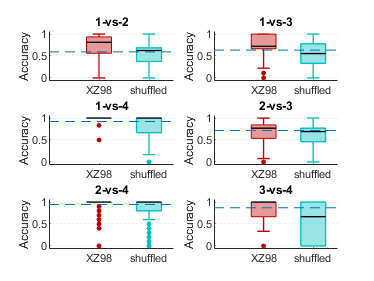

f = figure;
% 6 comparisons 1v2 2v3 3v4 1v4 2v4 1v3
combines = nchoosek(1:4,2);
for kd = 1:size(combines,1)
    X_temp = m_neural_bined(cat(2,idxs_2{combines(kd,:)}),:);
    
    % same vs neighbor
    kfold = 10; cvspace=45;
    Y_temp = Y(cat(2,idxs_2{combines(kd,:)}));
    perform = []; perform_shifted = [];
    for i = 1:10
        [perform_, perform_shifted_] = OnevOneDecoder(X_temp, Y_temp, kfold, cvspace,'lda');
        perform = [perform;perform_];
        perform_shifted = [perform_shifted;perform_shifted_];
    end
    a = subplot(3,2,kd,'Parent',f);
    XZBoxPlot({perform,perform_shifted},[],[],{MName,'shuffled'},[],a);
    random_guess_ = max(length(idxs_2{combines(kd,1)})/length(Y_temp), 1-length(idxs_2{combines(kd,1)})/length(Y_temp));
    line(a, a.XLim, [random_guess_, random_guess_],'LineStyle','--');
    title([num2str(combines(kd,1)), '-vs-', num2str(combines(kd,2))]);
    ylabel('Accuracy'); ylim('padded');
end